clear 
clearvars 
clc

%LOAD DATA

filename = "Data - National.xlsx";

DataI = readmatrix(filename,"Sheet","Innovation");
I1=DataI(5:14,12);
DataS = readmatrix(filename,"Sheet", "Stability");
S1=DataS(5:21,14);

DataNet = readmatrix(filename,"Sheet", "A.1 Network");
IFNet1=DataNet(5:14,2);
IFNet2=DataNet(5:14,3);
IFNet3=DataNet(5:14,4);
DataGen = readmatrix(filename,"Sheet", "A.2 Generation");
IFGen1=DataGen(4:33,2);
IFGen2=DataGen(4:28,3);
IFGen3=DataGen(4:13,4);
IFGen4=DataGen(4:19,5);
DataLan = readmatrix(filename,"Sheet", "A.3 Landscape");
IFLan1=DataLan(5:27,2);
IFLan2=DataLan(5:29,3);

DataRes = readmatrix(filename,"Sheet", "B.1 Resources");
IFRes1=DataRes(5:30,2);
IFRes2=DataRes(5:44,3);
IFRes3=DataRes(5:67,4);
DataFin = readmatrix(filename,"Sheet", "B.5 Financial");
IFFin1=DataFin(5:21,2);
IFFin2=DataFin(5:36,3);
IFFin3=DataFin(5:37,4);
DataInfr = readmatrix(filename,"Sheet", "B.7 Infrastructure");
IFInfr1=DataInfr(5:20,2);
IFInfr2=DataInfr(5:27,3);
IFInfr3=DataInfr(5:23,4);
IFInfr4=DataInfr(5:67,5);
IFInfr5=DataInfr(5:37,6);


%Pick from factors
%For this code:
X=S1;
IF1=IFFin1;
IF2=IFFin2;
IF3=IFFin3;
IF4=[1;2;3;4;5;6;7;8;9;10];
IF5=[1;2;3;4;5;6;7;8;9;10];


%Setting up results tables ready for final values

%Coefficents
%Row number must be at least equal to the number of loops (number of lags)
Value_store_matrixF1S = zeros(101,1); 
Value_store_matrixF2S = zeros(101,1);
Value_store_matrixF3S = zeros(101,1);
Value_store_matrixF4S = zeros(101,1);
Value_store_matrixF5S = zeros(101,1);
Value_store_matrixF1K = zeros(101,1);
Value_store_matrixF2K = zeros(101,1);
Value_store_matrixF3K = zeros(101,1);
Value_store_matrixF4K = zeros(101,1);
Value_store_matrixF5K = zeros(101,1);
Value_store_matrixF1P = zeros(101,1);
Value_store_matrixF2P = zeros(101,1);
Value_store_matrixF3P = zeros(101,1);
Value_store_matrixF4P = zeros(101,1);
Value_store_matrixF5P = zeros(101,1);

%Time Delays
Checking_matrixX =zeros(17,20);
Checking_matrixF1 =IF1;
Checking_matrixF2 =IF2;
Checking_matrixF3 =IF3;
Checking_matrixF4 =IF4;
Checking_matrixF5 =IF5;


lag_number = 0

IF2_cut =        NaN
    4.3000
   -2.5000
    4.5000
    4.1000
    4.1000
    1.1000
    1.2000
    4.2000
    6.0000


Impact on Innovation Factor 1 of Stability  from the previous year x0


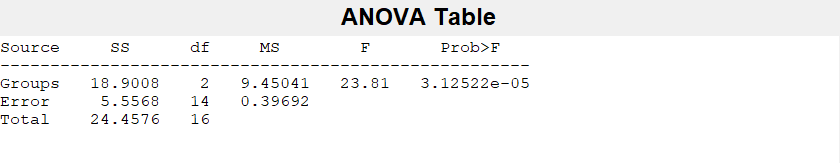

Impact on Innovation Factor 2 of Stability from the previous year x0


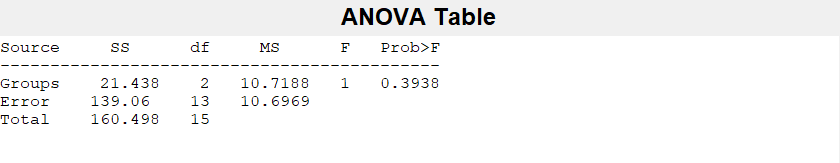

Impact on Innovation Factor 3 of Stability from the previous year x0


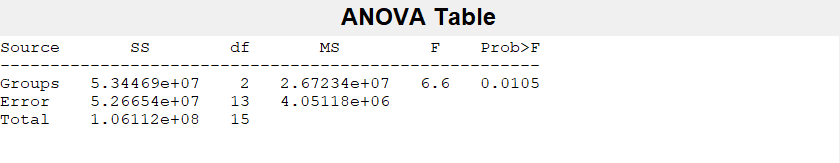

Impact on Innovation Factor 4 of Stability from the previous year x0


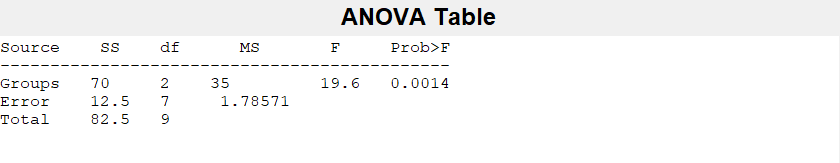

Impact on Innovation Factor 5 of Stability  from the previous year x0


lag_number = 1

IF2_cut =        NaN
    4.3000
   -2.5000
    4.5000
    4.1000
    4.1000
    1.1000
    1.2000
    4.2000
    6.0000


Impact on Innovation Factor 1 of Stability  from the previous year x1


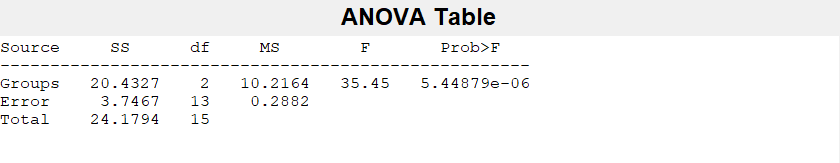

Impact on Innovation Factor 2 of Stability from the previous year x1


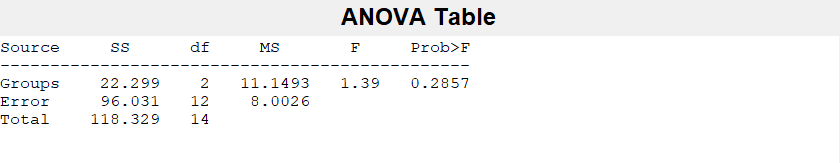

Impact on Innovation Factor 3 of Stability from the previous year x1


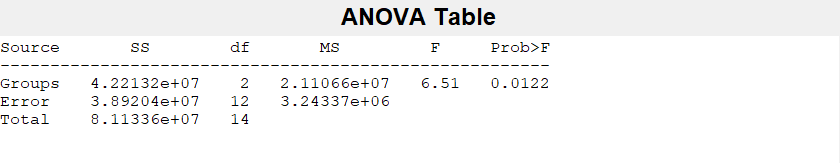

Impact on Innovation Factor 4 of Stability from the previous year x1


Impact on Innovation Factor 5 of Stability  from the previous year x1


lag_number = 2

IF2_cut =        NaN
    4.3000
   -2.5000
    4.5000
    4.1000
    4.1000
    1.1000
    1.2000
    4.2000
    6.0000


Impact on Innovation Factor 1 of Stability  from the previous year x2


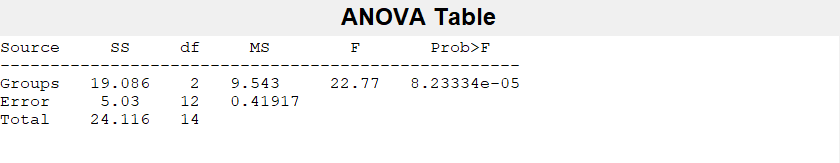

Impact on Innovation Factor 2 of Stability from the previous year x2


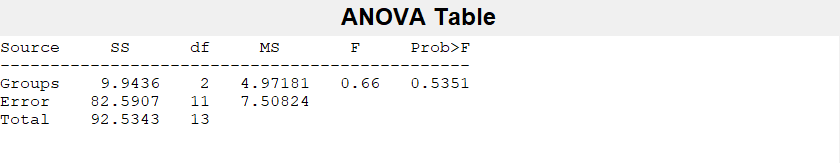

Impact on Innovation Factor 3 of Stability from the previous year x2


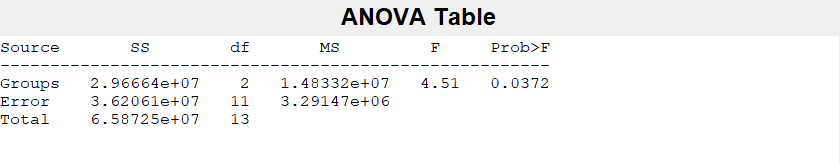

Impact on Innovation Factor 4 of Stability from the previous year x2


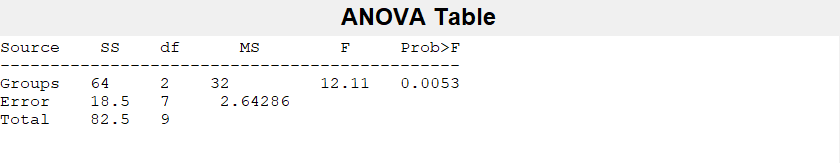

Impact on Innovation Factor 5 of Stability  from the previous year x2


lag_number = 3

IF2_cut =        NaN
    4.3000
   -2.5000
    4.5000
    4.1000
    4.1000
    1.1000
    1.2000
    4.2000
    6.0000


Impact on Innovation Factor 1 of Stability  from the previous year x3


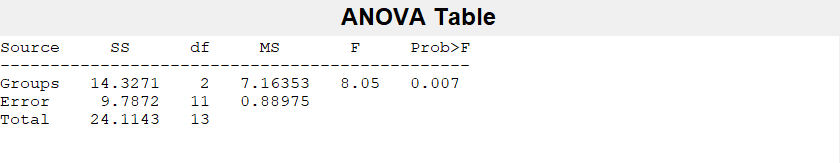

Impact on Innovation Factor 2 of Stability from the previous year x3


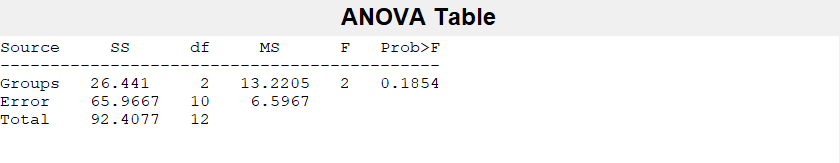

Impact on Innovation Factor 3 of Stability from the previous year x3


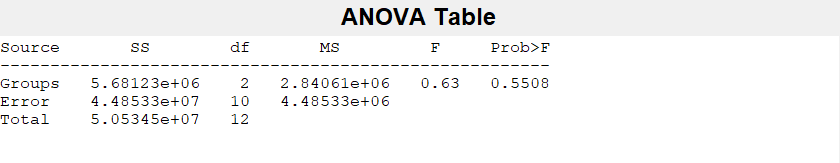

Impact on Innovation Factor 4 of Stability from the previous year x3


Impact on Innovation Factor 5 of Stability  from the previous year x3


lag_number = 4

IF2_cut =        NaN
    4.3000
   -2.5000
    4.5000
    4.1000
    4.1000
    1.1000
    1.2000
    4.2000
    6.0000


Impact on Innovation Factor 1 of Stability  from the previous year x4


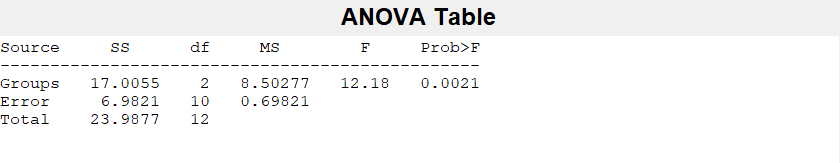

Impact on Innovation Factor 2 of Stability from the previous year x4


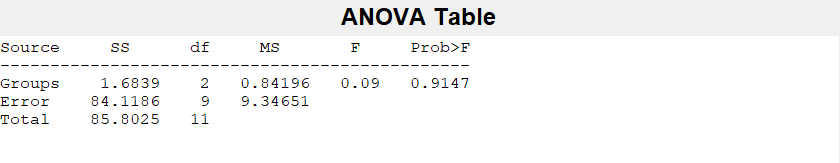

Impact on Innovation Factor 3 of Stability from the previous year x4


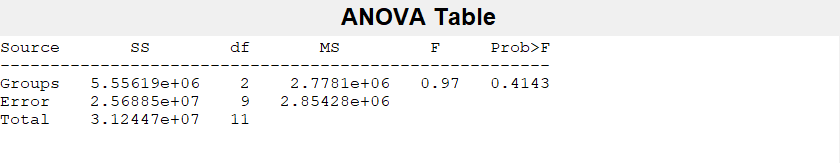

Impact on Innovation Factor 4 of Stability from the previous year x4


Impact on Innovation Factor 5 of Stability  from the previous year x4


lag_number = 5

IF2_cut =        NaN
    4.3000
   -2.5000
    4.5000
    4.1000
    4.1000
    1.1000
    1.2000
    4.2000
    6.0000


Impact on Innovation Factor 1 of Stability  from the previous year x5


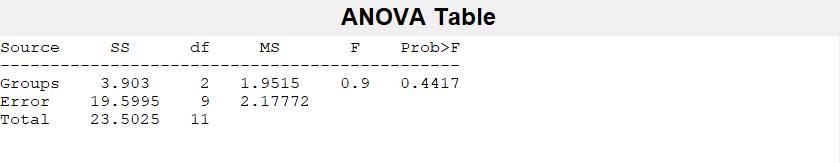

Impact on Innovation Factor 2 of Stability from the previous year x5


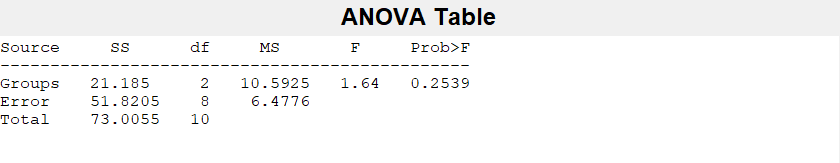

Impact on Innovation Factor 3 of Stability from the previous year x5


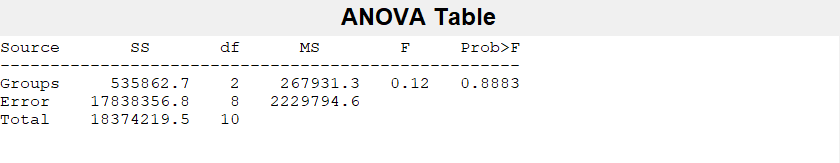

Impact on Innovation Factor 4 of Stability from the previous year x5


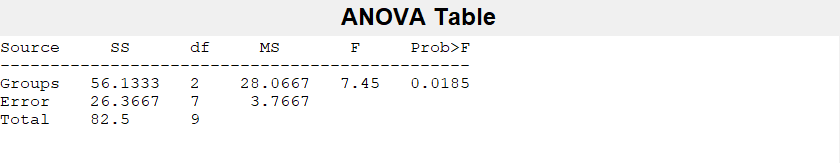

Impact on Innovation Factor 5 of Stability  from the previous year x5


lag_number = 6

IF2_cut =        NaN
    4.3000
   -2.5000
    4.5000
    4.1000
    4.1000
    1.1000
    1.2000
    4.2000
    6.0000


Impact on Innovation Factor 1 of Stability  from the previous year x6


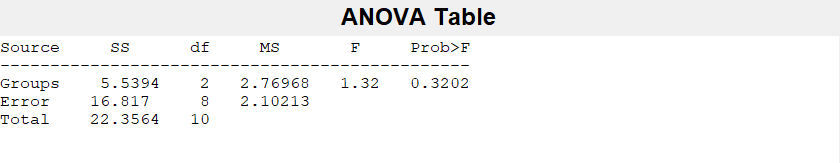

Impact on Innovation Factor 2 of Stability from the previous year x6


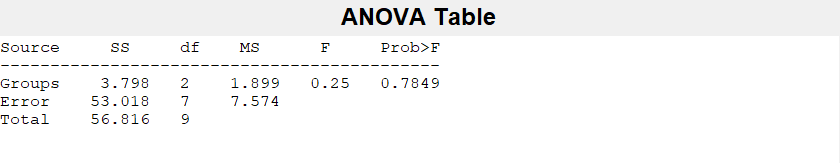

Impact on Innovation Factor 3 of Stability from the previous year x6


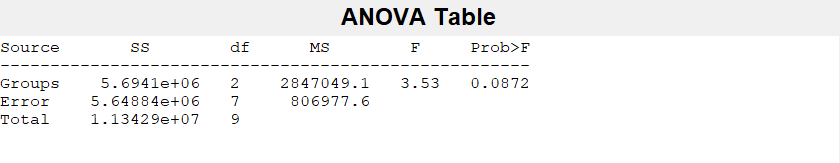

Impact on Innovation Factor 4 of Stability from the previous year x6


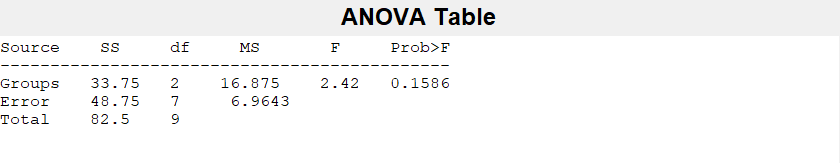

Impact on Innovation Factor 5 of Stability  from the previous year x6


lag_number = 7

IF2_cut =        NaN
    4.3000
   -2.5000
    4.5000
    4.1000
    4.1000
    1.1000
    1.2000
    4.2000
    6.0000


Impact on Innovation Factor 1 of Stability  from the previous year x7


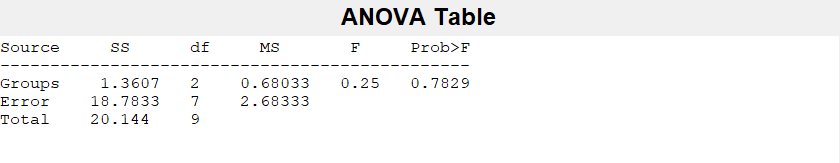

Impact on Innovation Factor 2 of Stability from the previous year x7


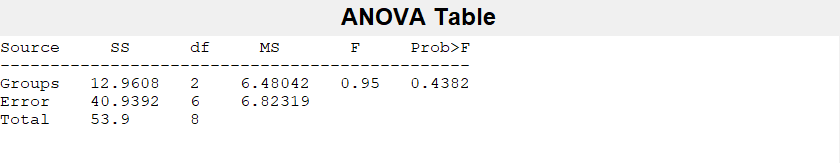

Impact on Innovation Factor 3 of Stability from the previous year x7


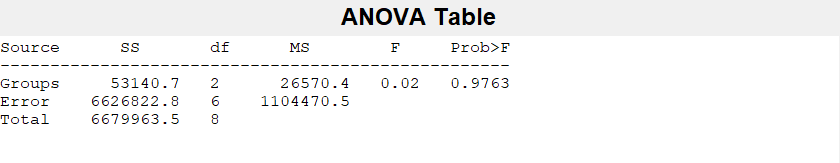

Impact on Innovation Factor 4 of Stability from the previous year x7


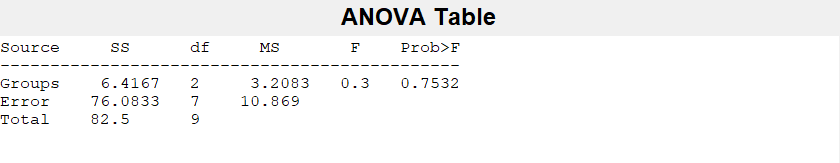

Impact on Innovation Factor 5 of Stability  from the previous year x7


lag_number = 8

IF2_cut =        NaN
    4.3000
   -2.5000
    4.5000
    4.1000
    4.1000
    1.1000
    1.2000
    4.2000
    6.0000


Impact on Innovation Factor 1 of Stability  from the previous year x8


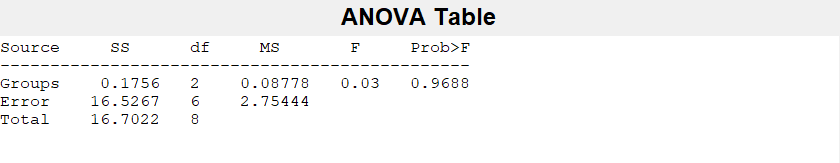

Impact on Innovation Factor 2 of Stability from the previous year x8


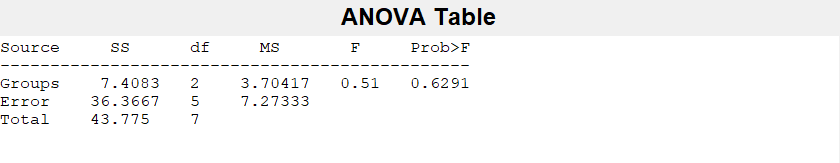

Impact on Innovation Factor 3 of Stability from the previous year x8


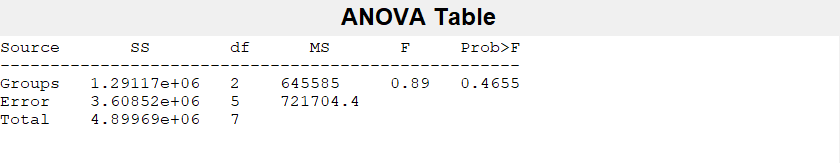

Impact on Innovation Factor 4 of Stability from the previous year x8


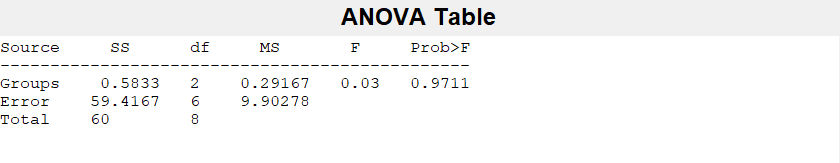

Impact on Innovation Factor 5 of Stability  from the previous year x8


lag_number = 9

IF2_cut =        NaN
    4.3000
   -2.5000
    4.5000
    4.1000
    4.1000
    1.1000
    1.2000
    4.2000
    6.0000


Impact on Innovation Factor 1 of Stability  from the previous year x9


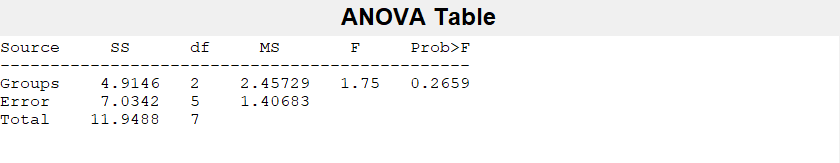

Impact on Innovation Factor 2 of Stability from the previous year x9


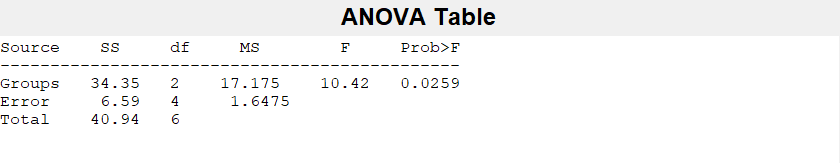

Impact on Innovation Factor 3 of Stability from the previous year x9


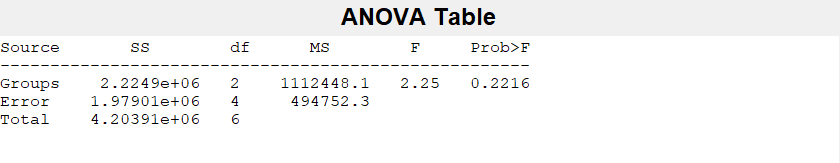

Impact on Innovation Factor 4 of Stability from the previous year x9


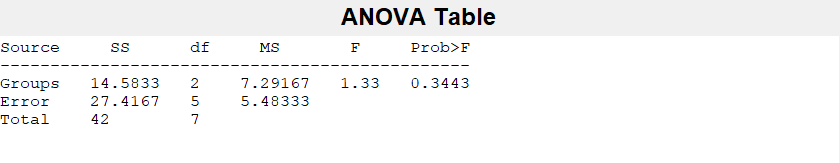

Impact on Innovation Factor 5 of Stability  from the previous year x9


%RUN TESTS FOR INCREASING LAG
for row=1:10
lag_number=row-1

%Cutting down data sets to be equal size
if length(IF1) > length(X)
    X1_cut=X;
    IF1_cut = IF1(1:length(X));
elseif length(IF1) < length(X)
    X1_cut = X(1:length(IF1));
    IF1_cut=IF1;
else 
    X1_cut=X;
    IF1_cut = IF1;
end

if length(IF2) > length(X)
    X2_cut=X;
    IF2_cut = IF2(1:length(X))
elseif length(IF2) < length(X)
    X2_cut = X(1:length(IF2));
    IF2_cut=IF2;
else
    X2_cut=X;
    IF2_cut = IF2;
end

if length(IF3) > length(X)
    X3_cut=X;
    IF3_cut = IF3(1:length(X));
elseif length(IF3) < length(X)
    X3_cut = X(1:length(IF3));
    IF3_cut=IF3;
else
    X3_cut=X;
    IF3_cut = IF3;
end

if length(IF4) > length(X)
    X4_cut=X;
    IF4_cut = IF4(1:length(X));
elseif length(IF4) < length(X)
    X4_cut = X(1:length(IF4));
    IF4_cut=IF4;
else
    X4_cut=X;
    IF4_cut = IF4;
end

if length(IF5) > length(X)
    X5_cut=X;
    IF5_cut = IF5(1:length(X));
elseif length(IF5) < length(X)
    X5_cut = X(1:length(IF5));
    IF5_cut=IF5;
else
    X5_cut=X;
    IF5_cut = IF5;
end


%Converting to rows for ANOVA 
X=X';
X1_cut=X1_cut';
X2_cut=X2_cut';
X3_cut=X3_cut';
X4_cut=X4_cut';
X5_cut=X5_cut';
IF1_cut=IF1_cut';
IF2_cut=IF2_cut';
IF3_cut=IF3_cut';
IF4_cut=IF4_cut';
IF5_cut=IF5_cut';

%Converting factor variables from continuous to nominal data for ANOVA
%Where 1 is least, 3 is most 

X1_edges=[min(X1_cut) min(X1_cut)+(1/3.*(max(X1_cut)-min(X1_cut))) min(X1_cut)+(2/3.*(max(X1_cut)-min(X1_cut))) max(X1_cut)];
X2_edges=[min(X2_cut) min(X2_cut)+(1/3.*(max(X2_cut)-min(X2_cut))) min(X2_cut)+(2/3.*(max(X2_cut)-min(X2_cut))) max(X2_cut)];
X3_edges=[min(X3_cut) min(X3_cut)+(1/3.*(max(X3_cut)-min(X3_cut))) min(X3_cut)+(2/3.*(max(X3_cut)-min(X3_cut))) max(X3_cut)];
X4_edges=[min(X4_cut) min(X4_cut)+(1/3.*(max(X4_cut)-min(X4_cut))) min(X4_cut)+(2/3.*(max(X4_cut)-min(X4_cut))) max(X4_cut)];
X5_edges=[min(X5_cut) min(X5_cut)+(1/3.*(max(X5_cut)-min(X5_cut))) min(X5_cut)+(2/3.*(max(X5_cut)-min(X5_cut))) max(X5_cut)];

X1_categories = discretize(X1_cut,X1_edges);
X2_categories = discretize(X2_cut,X2_edges);
X3_categories = discretize(X3_cut,X3_edges);
X4_categories = discretize(X4_cut,X4_edges);
X5_categories = discretize(X5_cut,X5_edges);

%Running ANOVA for impact of stability of innovation factors
disp(['Impact on Innovation Factor 1 of Stability  from the previous year x' , num2str(lag_number)])
[p_1]=anova1(IF1_cut, X1_categories);
disp(['Impact on Innovation Factor 2 of Stability from the previous year x' , num2str(lag_number)])
[p_2]=anova1(IF2_cut, X2_categories);
disp(['Impact on Innovation Factor 3 of Stability from the previous year x' , num2str(lag_number)])
[p_3]=anova1(IF3_cut, X3_categories);
disp(['Impact on Innovation Factor 4 of Stability from the previous year x' , num2str(lag_number)])
[p_4]=anova1(IF4_cut, X4_categories);
disp(['Impact on Innovation Factor 5 of Stability  from the previous year x' , num2str(lag_number)])
[p_5]=anova1(IF5_cut, X5_categories);

%Converting back to columns 
X=X';
X1_cut=X1_cut';
X2_cut=X2_cut';
X3_cut=X3_cut';
X4_cut=X4_cut';
X5_cut=X5_cut';
IF1_cut=IF1_cut';
IF2_cut=IF2_cut';
IF3_cut=IF3_cut';
IF4_cut=IF4_cut';
IF5_cut=IF5_cut';

%Creating table to check lagged stability
Checking_matrixX (:,row) = X;

%Running coefficient calcs
%%--------------- 

%Factor 1
if p_1<0.05 && sum(isnan(IF1_cut))<6 

SpearmanCoefficientF1 = corr(X1_cut, IF1_cut, 'type', 'Spearman', 'Rows','complete');
KendallCoefficientF1 = corr(X1_cut, IF1_cut, 'type', 'Kendall', 'Rows','complete');
PearsonCoefficientF1 = corr(X1_cut, IF1_cut, 'type', 'Pearson', 'Rows','complete');

if SpearmanCoefficientF1 == 0
SpearmanCoefficientF1 = NaN;
end
if KendallCoefficientF1 == 0
KendallCoefficientF1 = NaN;
end
if PearsonCoefficientF1 == 0
PearsonCoefficientF1 = NaN;
end

else
SpearmanCoefficientF1 = NaN ;
KendallCoefficientF1 = NaN ;
PearsonCoefficientF1 = NaN ; 

end 

%Add factor to table
Value_store_matrixF1S (row,1) = SpearmanCoefficientF1;
Value_store_matrixF1K (row,1) = KendallCoefficientF1;
Value_store_matrixF1P (row,1) = PearsonCoefficientF1;



%Factor 2
if p_2<0.05 && sum(isnan(IF2_cut))<6

SpearmanCoefficientF2 = corr(X2_cut, IF2_cut, 'type', 'Spearman', 'Rows','complete');
KendallCoefficientF2 = corr(X2_cut, IF2_cut, 'type', 'Kendall', 'Rows','complete');
PearsonCoefficientF2 = corr(X2_cut, IF2_cut, 'type', 'Pearson', 'Rows','complete');

if SpearmanCoefficientF2 == 0
SpearmanCoefficientF2 = NaN;
end
if KendallCoefficientF2 == 0
KendallCoefficientF2 = NaN;
end
if PearsonCoefficientF2 == 0
PearsonCoefficientF2 = NaN;
end

else
SpearmanCoefficientF2 = NaN ;
KendallCoefficientF2 = NaN ;
PearsonCoefficientF2 = NaN ; 

end 

%Add factor to table
Value_store_matrixF2S (row,1) = SpearmanCoefficientF2;
Value_store_matrixF2K (row,1) = KendallCoefficientF2;
Value_store_matrixF2P (row,1) = PearsonCoefficientF2;


%Factor 3
if p_3<0.05 && sum(isnan(IF3_cut))<6

SpearmanCoefficientF3 = corr(X3_cut, IF3_cut, 'type', 'Spearman', 'Rows','complete');
KendallCoefficientF3 = corr(X3_cut, IF3_cut, 'type', 'Kendall', 'Rows','complete');
PearsonCoefficientF3 = corr(X3_cut, IF3_cut, 'type', 'Pearson', 'Rows','complete');

if SpearmanCoefficientF3 == 0
SpearmanCoefficientF3 = NaN;
end
if KendallCoefficientF3 == 0
KendallCoefficientF3 = NaN;
end
if PearsonCoefficientF3 == 0
PearsonCoefficientF3 = NaN;
end

else
SpearmanCoefficientF3 = NaN ;
KendallCoefficientF3 = NaN ;
PearsonCoefficientF3 = NaN ; 

end 

%Add factor to table
Value_store_matrixF3S (row,1) = SpearmanCoefficientF3;
Value_store_matrixF3K (row,1) = KendallCoefficientF3;
Value_store_matrixF3P (row,1) = PearsonCoefficientF3;

%Factor 4
if p_4<0.05 && sum(isnan(IF4_cut))<6

SpearmanCoefficientF4 = corr(X4_cut, IF4_cut, 'type', 'Spearman', 'Rows','complete');
KendallCoefficientF4 = corr(X4_cut, IF4_cut, 'type', 'Kendall', 'Rows','complete');
PearsonCoefficientF4 = corr(X4_cut, IF4_cut, 'type', 'Pearson', 'Rows','complete');

if SpearmanCoefficientF4 == 0
SpearmanCoefficientF4 = NaN;
end
if KendallCoefficientF4 == 0
KendallCoefficientF4 = NaN;
end
if PearsonCoefficientF4 == 0
PearsonCoefficientF4 = NaN;
end

else
SpearmanCoefficientF4 = NaN ;
KendallCoefficientF4 = NaN ;
PearsonCoefficientF4 = NaN ; 

end 

%Add factor to table
Value_store_matrixF4S (row,1) = SpearmanCoefficientF4;
Value_store_matrixF4K (row,1) = KendallCoefficientF4;
Value_store_matrixF4P (row,1) = PearsonCoefficientF4;

%Factor 5
if p_5<0.05 && sum(isnan(IF5_cut))<6

SpearmanCoefficientF5 = corr(X5_cut, IF5_cut, 'type', 'Spearman', 'Rows','complete');
KendallCoefficientF5 = corr(X5_cut, IF5_cut, 'type', 'Kendall', 'Rows','complete');
PearsonCoefficientF5 = corr(X5_cut, IF5_cut, 'type', 'Pearson', 'Rows','complete');

if SpearmanCoefficientF5 == 0
SpearmanCoefficientF5 = NaN;
end
if KendallCoefficientF5 == 0
KendallCoefficientF5 = NaN;
end
if PearsonCoefficientF5 == 0
PearsonCoefficientF5 = NaN;
end

else
SpearmanCoefficientF5 = NaN ;
KendallCoefficientF5 = NaN ;
PearsonCoefficientF5 = NaN ; 

end 

%Add factor to table
Value_store_matrixF5S (row,1) = SpearmanCoefficientF5;
Value_store_matrixF5K (row,1) = KendallCoefficientF5;
Value_store_matrixF5P (row,1) = PearsonCoefficientF5;

%%---------------


%Lag stability data for next loop 
for i = 1:length(X)-1 
X(i) = X(i+1);
end 
X(end) = NaN;


%Break conditions:
%If the lagging has led to so few data points that no reasonable conclusion
%can be made
if sum(isnan(IF1_cut))>12 && sum(isnan(IF2_cut))>12 && sum(isnan(IF3_cut))>12 && sum(isnan(IF4_cut))>12 && sum(isnan(IF5_cut))>12, break, end 


end

%RESULTS TABLE
Checking_matrixX=array2table(Checking_matrixX) 

Checking_matrixX = 17×20 table
    Checking_matrixX1    Checking_matrixX2    Checking_matrixX3    Checking_matrixX4    Checking_matrixX5    Checking_matrixX6    Checking_matrixX7    Checking_matrixX8    Checking_matrixX9    Checking_matrixX10    Checking_matrixX11    Checking_matrixX12    Checking_matrixX13    Checking_matrixX14    Checking_matrixX15    Checking_matrixX16    Checking_matrixX17    Checking_matrixX18    Checking_matrixX19    Checking_matrixX20
    _________________    _________________    _________________    _________________    _________________    


%Table for factor 1
Checking_matrixF1=array2table(Checking_matrixF1) 

Checking_matrixF1 = 17×1 table
    Checking_matrixF1
    _________________

           2.9       
           3.2       
           3.3       
           3.6       
           3.9       
           4.2       
           6.2       
           6.2       
           6.5       
           6.4       
           6.2       
           5.9       
           5.6       
           5.3       
             5       
           4.7       



Value_store_matrixF1S = nonzeros(Value_store_matrixF1S);
Value_store_matrixF1K = nonzeros(Value_store_matrixF1K);
Value_store_matrixF1P = nonzeros(Value_store_matrixF1P);

TF1S = array2table(Value_store_matrixF1S, 'Variablenames', "Spearman's Correlation Coefficient");
TF1K = array2table(Value_store_matrixF1K, 'Variablenames', "Kendall's Correlation Coefficient");
TF1P = array2table(Value_store_matrixF1P, 'Variablenames', "Pearson's Correlation Coefficient");

L1=max([size(Value_store_matrixF1S,1), size(Value_store_matrixF1K,1) , size(Value_store_matrixF1P,1)]);
Lag_store_matrixF1= 0:1:L1-1;
Lags_for_table_matrixF1= Lag_store_matrixF1';
TLF1 = array2table(Lags_for_table_matrixF1, 'Variablenames', "Xears Lagged");

disp('Significant relationships between Stability and Innovation Factor 1 for Increasing Lag:')

Significant relationships between Stability and Innovation Factor 1 for Increasing Lag:


T1 = [TLF1 TF1S TF1K TF1P];

if isempty(T1)==1
disp('No significant relationships found between Stability and Innovation factor 1')
else
    T1
end

T1 = 10×4 table
    Xears Lagged    Spearman's Correlation Coefficient    Kendall's Correlation Coefficient    Pearson's Correlation Coefficient
    ____________    __________________________________    _________________________________    _________________________________

         0                       0.66585                               0.49817                              0.81861             
         1                       0.76107                               0.61608                              0.86669             
         2                       0.78137                               0.63775                              0.85716             
         3                       0.83224                               0.67049                              0.85756             
         4                       0.87847                               0.


%Table for factor 2
Checking_matrixF2=array2table(Checking_matrixF2)  

Checking_matrixF2 = 32×1 table
    Checking_matrixF2
    _________________

           NaN       
           4.3       
          -2.5       
           4.5       
           4.1       
           4.1       
           1.1       
           1.2       
           4.2       
             6       
           4.8       
           7.4       
           7.3       
           1.2       
           3.3       
           8.9       



Value_store_matrixF2S = nonzeros(Value_store_matrixF2S);
Value_store_matrixF2K = nonzeros(Value_store_matrixF2K);
Value_store_matrixF2P = nonzeros(Value_store_matrixF2P);

TF2S = array2table(Value_store_matrixF2S, 'Variablenames', "Spearman's Correlation Coefficient");
TF2K = array2table(Value_store_matrixF2K, 'Variablenames', "Kendall's Correlation Coefficient");
TF2P = array2table(Value_store_matrixF2P, 'Variablenames', "Pearson's Correlation Coefficient");

L2=max([size(Value_store_matrixF2S,1), size(Value_store_matrixF2K,1) , size(Value_store_matrixF2P,1)]);
Lag_store_matrixF2= 0:1:L2-1;
Lags_for_table_matrixF2= Lag_store_matrixF2';
TLF2 = array2table(Lags_for_table_matrixF2, 'Variablenames', "Xears Lagged");

disp('Significant relationships between Stability and Innovation Factor 2 for Increasing Lag:')

Significant relationships between Stability and Innovation Factor 2 for Increasing Lag:


T2 = [TLF2 TF2S TF2K TF2P];

if isempty(T2)==1
disp('No significant relationships found between Stability and Innovation factor 2')
else
    T2
end

T2 = 10×4 table
    Xears Lagged    Spearman's Correlation Coefficient    Kendall's Correlation Coefficient    Pearson's Correlation Coefficient
    ____________    __________________________________    _________________________________    _________________________________

         0                           NaN                                   NaN                                  NaN             
         1                           NaN                                   NaN                                  NaN             
         2                           NaN                                   NaN                                  NaN             
         3                           NaN                                   NaN                                  NaN             
         4                           NaN                                 


%Table for factor 3
Checking_matrixF3=array2table(Checking_matrixF3)

Checking_matrixF3 = 33×1 table
    Checking_matrixF3
    _________________

            NaN      
          26111      
          25362      
          26352      
          25544      
          24863      
          24211      
          24290      
          24356      
          23721      
          22703      
          21970      
          20751      
          19615      
          19770      
          19500      



Value_store_matrixF3S = nonzeros(Value_store_matrixF3S);
Value_store_matrixF3K = nonzeros(Value_store_matrixF3K);
Value_store_matrixF3P = nonzeros(Value_store_matrixF3P);

TF3S = array2table(Value_store_matrixF3S, 'Variablenames', "Spearman's Correlation Coefficient");
TF3K = array2table(Value_store_matrixF3K, 'Variablenames', "Kendall's Correlation Coefficient");
TF3P = array2table(Value_store_matrixF3P, 'Variablenames', "Pearson's Correlation Coefficient");

L3=max([size(Value_store_matrixF3S,1), size(Value_store_matrixF3K,1) , size(Value_store_matrixF3P,1)]);
Lag_store_matrixF3= 0:1:L3-1;
Lags_for_table_matrixF3= Lag_store_matrixF3';
TLF3 = array2table(Lags_for_table_matrixF3, 'Variablenames', "Xears Lagged");

disp('Significant relationships between Stability and Innovation Factor 3 for Increasing Lag:')

Significant relationships between Stability and Innovation Factor 3 for Increasing Lag:


T3 = [TLF3 TF3S TF3K TF3P];

if isempty(T3)==1
disp('No significant relationships found between Stability and Innovation factor 3')
else
    T3
end

T3 = 10×4 table
    Xears Lagged    Spearman's Correlation Coefficient    Kendall's Correlation Coefficient    Pearson's Correlation Coefficient
    ____________    __________________________________    _________________________________    _________________________________

         0                       -0.77647                             -0.63333                             -0.71667             
         1                       -0.74286                             -0.61905                             -0.67645             
         2                       -0.66154                             -0.51648                             -0.58599             
         3                            NaN                                  NaN                                  NaN             
         4                            NaN                                


%Table for factor 4
Checking_matrixF4=array2table(Checking_matrixF4) 

Checking_matrixF4 = 10×1 table
    Checking_matrixF4
    _________________

            1        
            2        
            3        
            4        
            5        
            6        
            7        
            8        
            9        
           10        



Value_store_matrixF4S = nonzeros(Value_store_matrixF4S);
Value_store_matrixF4K = nonzeros(Value_store_matrixF4K);
Value_store_matrixF4P = nonzeros(Value_store_matrixF4P);

TF4S = array2table(Value_store_matrixF4S, 'Variablenames', "Spearman's Correlation Coefficient");
TF4K = array2table(Value_store_matrixF4K, 'Variablenames', "Kendall's Correlation Coefficient");
TF4P = array2table(Value_store_matrixF4P, 'Variablenames', "Pearson's Correlation Coefficient");

L4=max([size(Value_store_matrixF4S,1), size(Value_store_matrixF4K,1) , size(Value_store_matrixF4P,1)]);
Lag_store_matrixF4= 0:1:L4-1;
Lags_for_table_matrixF4= Lag_store_matrixF4';
TLF4 = array2table(Lags_for_table_matrixF4, 'Variablenames', "Xears Lagged");

disp('Significant relationships between Stability and Innovation Factor 4 for Increasing Lag:')

Significant relationships between Stability and Innovation Factor 4 for Increasing Lag:


T4 = [TLF4 TF4S TF4K TF4P];

if isempty(T4)==1
disp('No significant relationships found between Stability and Innovation factor 4')
else
    T4
end

T4 = 10×4 table
    Xears Lagged    Spearman's Correlation Coefficient    Kendall's Correlation Coefficient    Pearson's Correlation Coefficient
    ____________    __________________________________    _________________________________    _________________________________

         0                       0.98788                               0.95556                              0.98394             
         1                       0.98788                               0.95556                              0.97267             
         2                       0.95152                               0.86667                              0.92667             
         3                       0.95152                               0.86667                              0.92525             
         4                       0.95152                               0.


%Table for factor 5
Checking_matrixF5=array2table(Checking_matrixF5) 

Checking_matrixF5 = 10×1 table
    Checking_matrixF5
    _________________

            1        
            2        
            3        
            4        
            5        
            6        
            7        
            8        
            9        
           10        



Value_store_matrixF5S = nonzeros(Value_store_matrixF5S);
Value_store_matrixF5K = nonzeros(Value_store_matrixF5K);
Value_store_matrixF5P = nonzeros(Value_store_matrixF5P);

TF5S = array2table(Value_store_matrixF5S, 'Variablenames', "Spearman's Correlation Coefficient");
TF5K = array2table(Value_store_matrixF5K, 'Variablenames', "Kendall's Correlation Coefficient");
TF5P = array2table(Value_store_matrixF5P, 'Variablenames', "Pearson's Correlation Coefficient");

L5=max([size(Value_store_matrixF5S,1), size(Value_store_matrixF5K,1) , size(Value_store_matrixF5P,1)]);
Lag_store_matrixF5= 0:1:L5-1;
Lags_for_table_matrixF5= Lag_store_matrixF5';
TLF5 = array2table(Lags_for_table_matrixF5, 'Variablenames', "Xears Lagged");

disp('Significant relationships between Stability and Innovation Factor 5 for Increasing Lag:')

Significant relationships between Stability and Innovation Factor 5 for Increasing Lag:


T5 = [TLF5 TF5S TF5K TF5P];

if isempty(T5)==1
disp('No significant relationships found between Stability and Innovation factor 5')
else
    T5
end

T5 = 10×4 table
    Xears Lagged    Spearman's Correlation Coefficient    Kendall's Correlation Coefficient    Pearson's Correlation Coefficient
    ____________    __________________________________    _________________________________    _________________________________

         0                       0.98788                               0.95556                              0.98394             
         1                       0.98788                               0.95556                              0.97267             
         2                       0.95152                               0.86667                              0.92667             
         3                       0.95152                               0.86667                              0.92525             
         4                       0.95152                               0.